clear all
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Basic Fast Wavelet Transform demo in 2D
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Changeable parameters

%imname = 'shape_plus.png';    % simplest
imname = "shape_House2.png"   % House

imname = "shape_House2.png"


wavelet_type = 'haar';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Read in the image

I = imread(imname);
disp(size(I))

   627   879     3



disp(numel(size(I)))

     3




if numel( size(I) ) == 3
    I = (double(rgb2gray(I)));
else 
    I = (double(I));
end

disp(size(I))

   627   879



Isize = size(I, 1);
disp(Isize)

   627



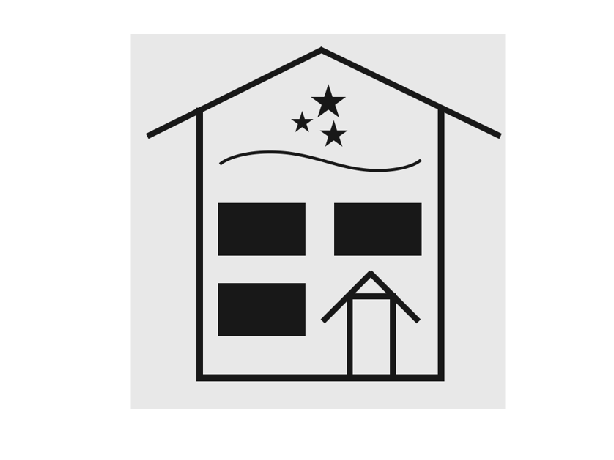

%----------------------------------------------
% Resize to 512 if using the House image...
if strcmp('shape_House2.png', imname)
    I = I(1:626, 125:626+125-1);
    Isize = size(I, 1);
    I = imresize(I, (512/Isize));
    Isize = size(I, 1);
end
% %----------------------------------------------
% 
% %----------------------------------------------
% %Resize to 256 if using the Plus image...
if strcmp('shape_plus.png', imname)
    I = I(10:470, 40:500);
    Isize = size(I, 1);
    I = imresize(I, (256/Isize));
    Isize = size(I, 1);
end
%----------------------------------------------

%whos I

imshow(I, [], 'InitialMagnification', 'fit')

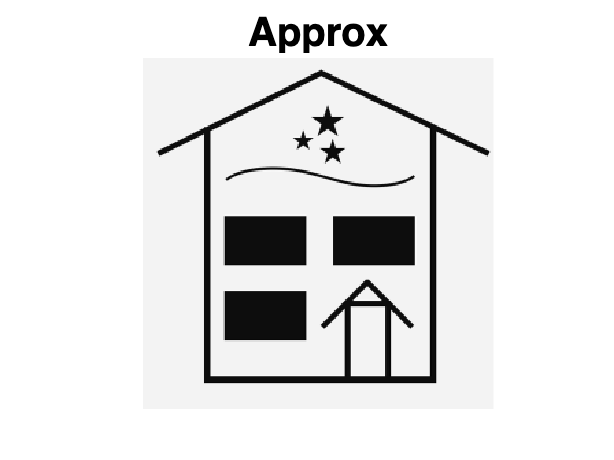

% Perform the FWT one level at a time:

% Retrieve the 1st level approximation and detail coefficients:

[xa, xh, xv, xd] = dwt2( I, wavelet_type );

% Display

imshow(xa, [], 'InitialMagnification', 'fit')   % Approximation
title('Approx', 'FontSize', 20);

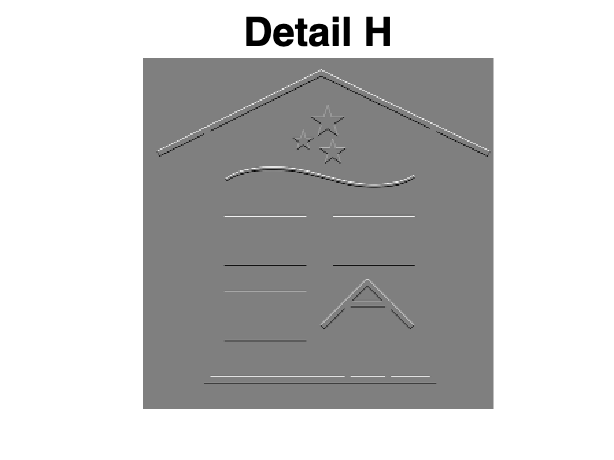

imshow(xh, [], 'InitialMagnification', 'fit')   % Detail Horizontal
title('Detail H', 'FontSize', 20);

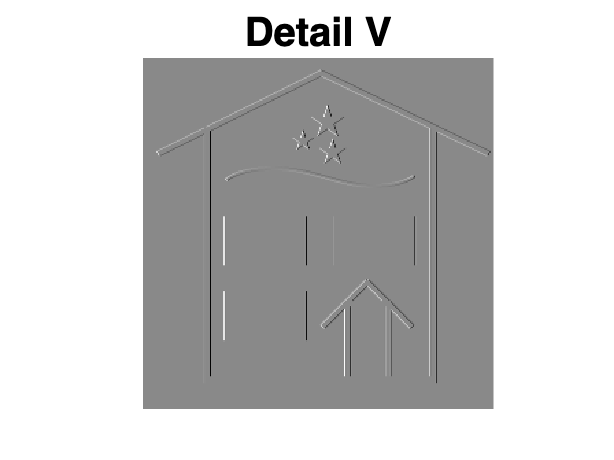

imshow(xv, [], 'InitialMagnification', 'fit')   % Detail Vertical
title('Detail V', 'FontSize', 20);

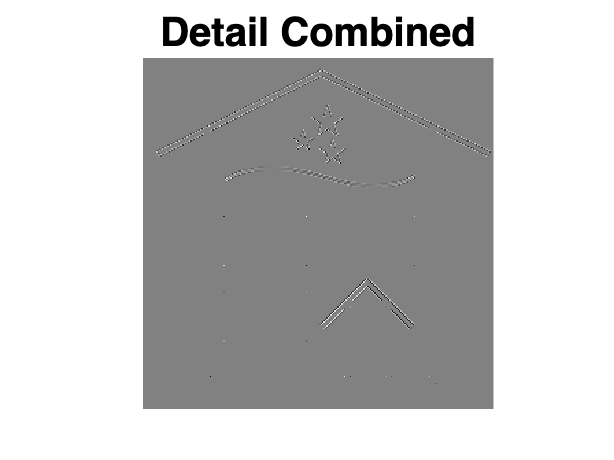

imshow(xd, [], 'InitialMagnification', 'fit')   % Detail combined
title('Detail Combined', 'FontSize', 20);

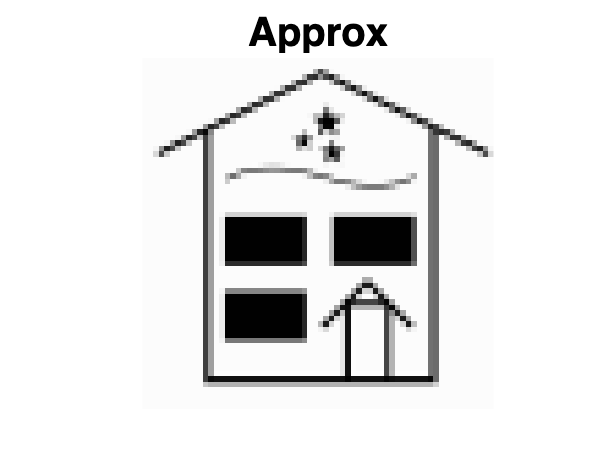


% Retrieve the 2nd level approximation and detail coefficients:

[xaa, xhh, xvv, xdd] = dwt2( xa, wavelet_type ); % 2nd level

% Go deeper (not saving levels separately)
% 
 [xaN, xhN, xvN, xdN] = dwt2( xaa, wavelet_type );   % 3rd level
% [xaN, xhN, xvN, xdN] = dwt2( xaN, wavelet_type );   % 4th level
% [xaN, xhN, xvN, xdN] = dwt2( xaN, wavelet_type );   % 5th level
% 
% % Display?

imshow(xaN, [], 'InitialMagnification', 'fit')
title('Approx', 'FontSize', 20);

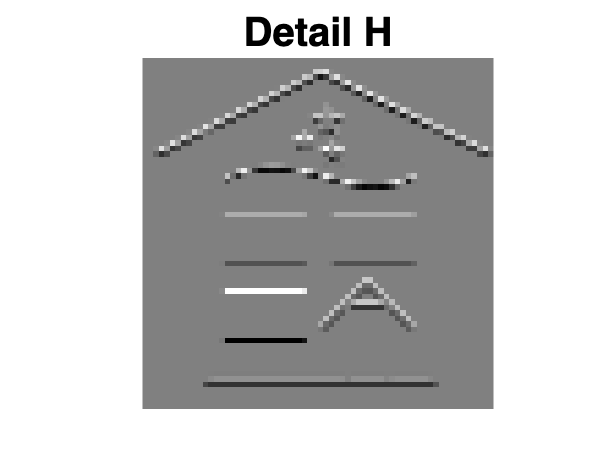

imshow(xhN, [], 'InitialMagnification', 'fit')
title('Detail H', 'FontSize', 20);

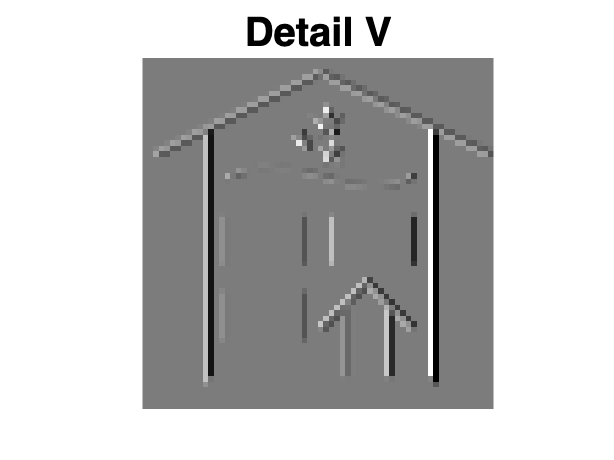

imshow(xvN, [], 'InitialMagnification', 'fit')
title('Detail V', 'FontSize', 20);

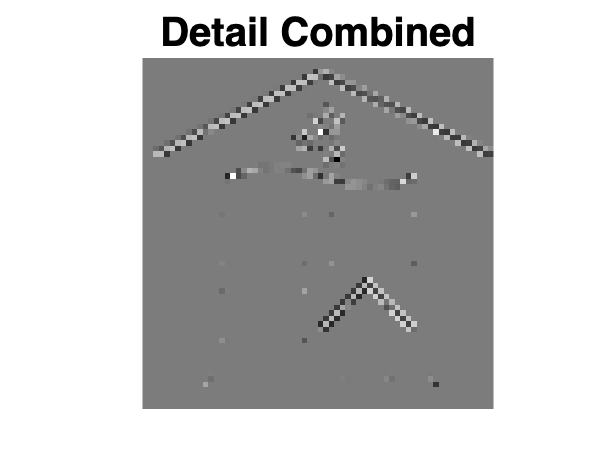

imshow(xdN, [], 'InitialMagnification', 'fit')
title('Detail Combined', 'FontSize', 20);

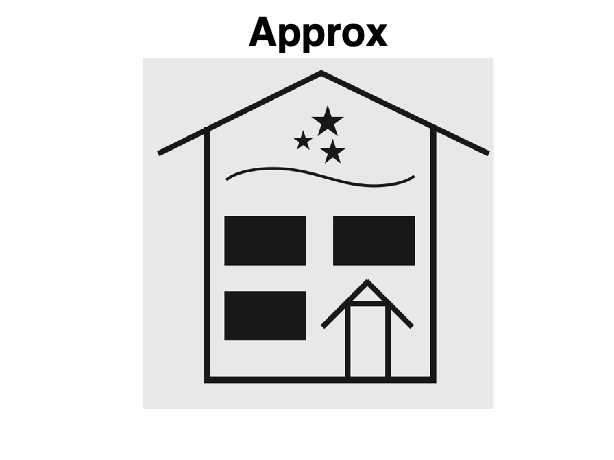

% Reconstruct from 3rd level:

xa_rec2 = idwt2(xaN    , xhN, xvN, xdN, wavelet_type);  % Level 2 reconstruction

xa_rec1 = idwt2(xa_rec2, xhh, xvv, xdd, wavelet_type);  % Level 1 reconstruction

xa_rec  = idwt2(xa_rec1, xh , xv , xd , wavelet_type);  % Original domain reconstruction

imshow(xa_rec, [], 'InitialMagnification', 'fit')
title('Approx', 'FontSize', 20);